# Miniprojekt 3 - Tone Control

## Indledning

VIl vil i denne opgave vil vi anvende digital signalbehandling til at justere lyden i en Lyngdorf TDAI-1120 forstærker. Vi vil arbejde audiofiltre og lgoritmer til at opnå en løsning. Forstærkeren indeholder en DSP med forskellige features som tonecontrol, Room Correction og Speaker EQ. Vi vil i denne opgave arbejde med Tone Control. 

## Formål

Vi vil analysere og designe tonekontrol som skal kunne ændre på gain af hhv. bassen og diskanten. Tonekontrol er det førsteled i DSP'en som ses i billedet nedenfor.

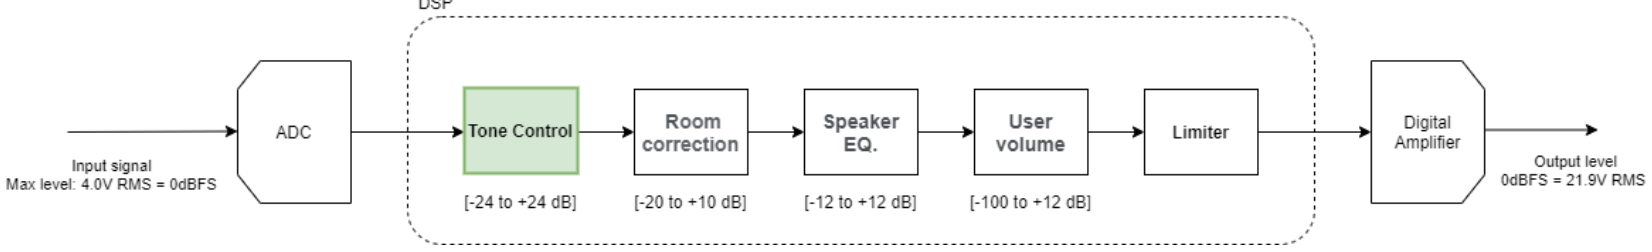

Dette vil vi gøre ved at konstruere to shelving-filtre i kaskade hvor den ene er til bas og den anden til diskant. Kravene er således:

- 2 x IIR filtre (shelving)

- Niveau i hvert bånd +-24dB

## Analyse

Først tages udgangspunkt i diskanten. Ved diskanten skal de høje frekvenser igennem, dvs. et højpas filter skal konstrueres.

### *FilterSelect *funktion

## Anvendelse af *Tonekontrol*

%Fs  = 44100;    % Sampelfrekvens
[limbo,Fs]=audioread("Limbo.mp3");

Fcb         = 80;      % Cutoff for bass
Fct         = 3500;     % Cutoff for treble

gainBass    =16;       % Gain for bass
gainTreble  =-12;       % Gain for treble

[Bbas,Abas] = FilterSelect(Fs,gainBass,Fcb,"bass");         % b og a koeffitienter for bass
[Btreb,Atreb] = FilterSelect(Fs,gainTreble,Fct,"treble");   % b og a koeffitienter for treble

Hbas=dfilt.df2t(Bbas,Abas);     % IIR filter for bass
Htreb=dfilt.df2t(Btreb,Atreb);  % IIR filter for treble
Hcas=dfilt.cascade(Hbas,Htreb); % Kaskade kobling af de to IIR filtre


 
filteretLimbo=filter(Hcas,limbo);
soundsc(filteretLimbo,Fs)

 
soundsc(limbo,Fs)

 
clear sound

ddmkds

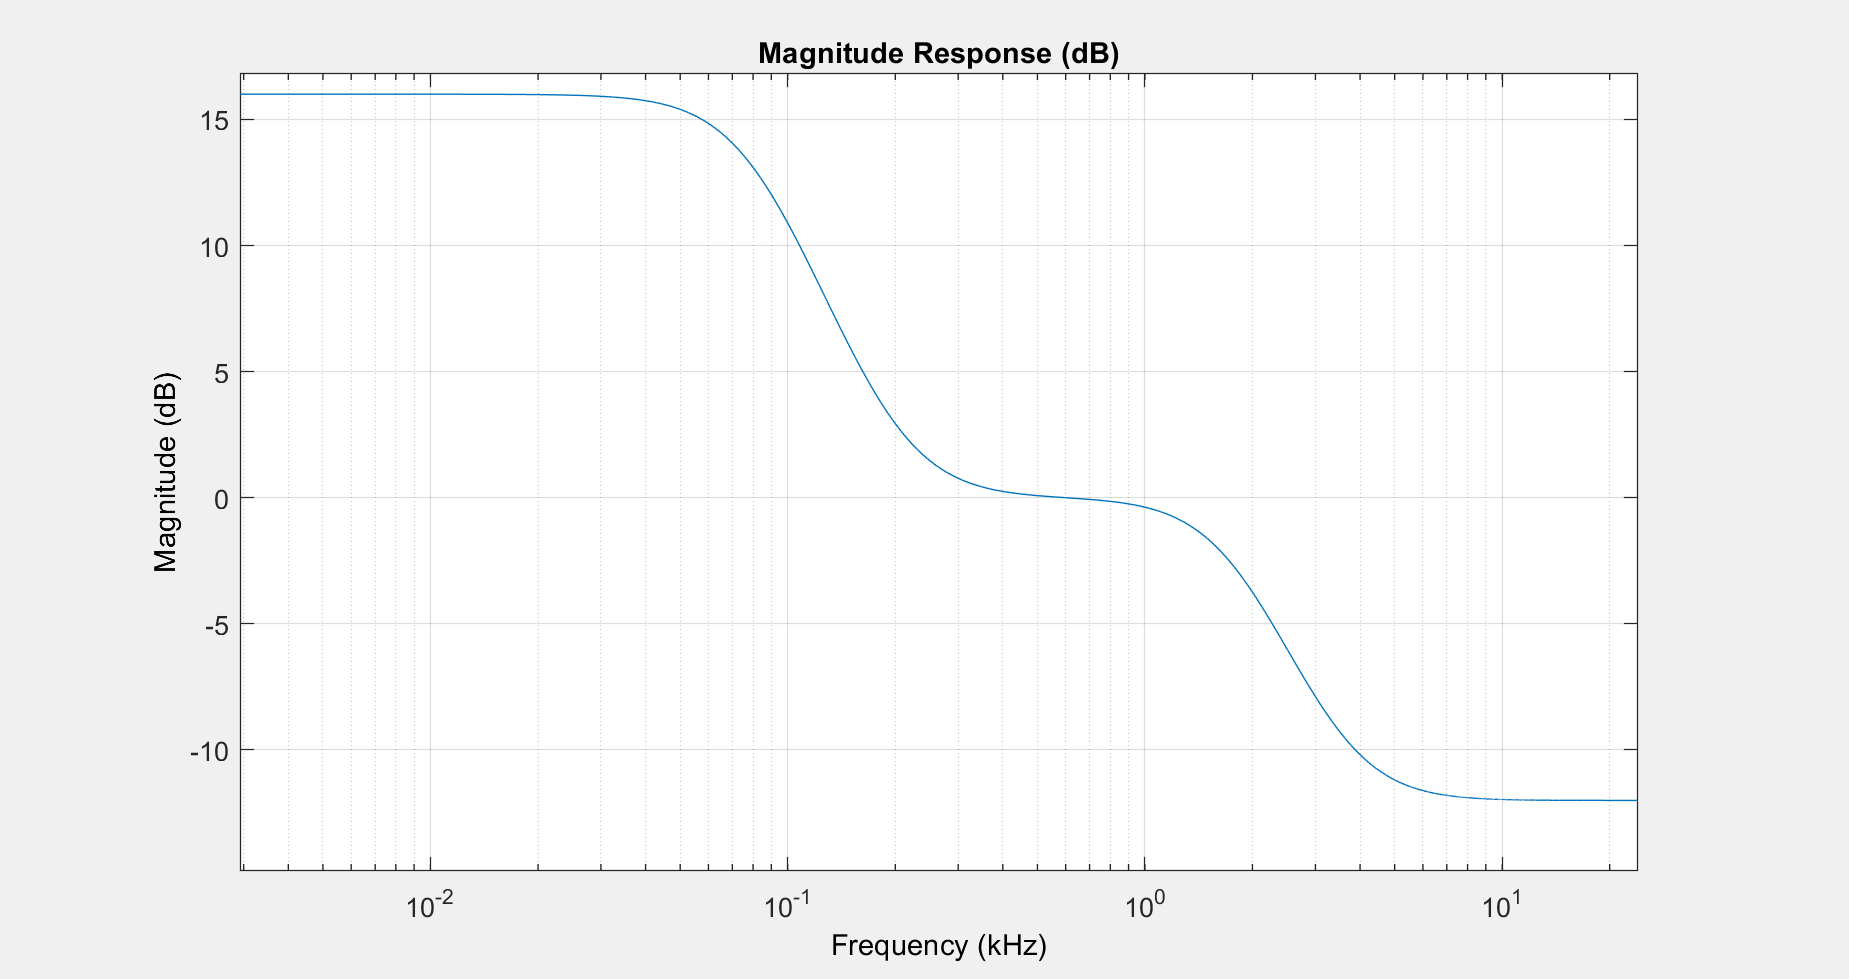

fvtool(Hcas, 'Analysis', 'magnitude', 'Fs', Fs);

dfkopsdsd

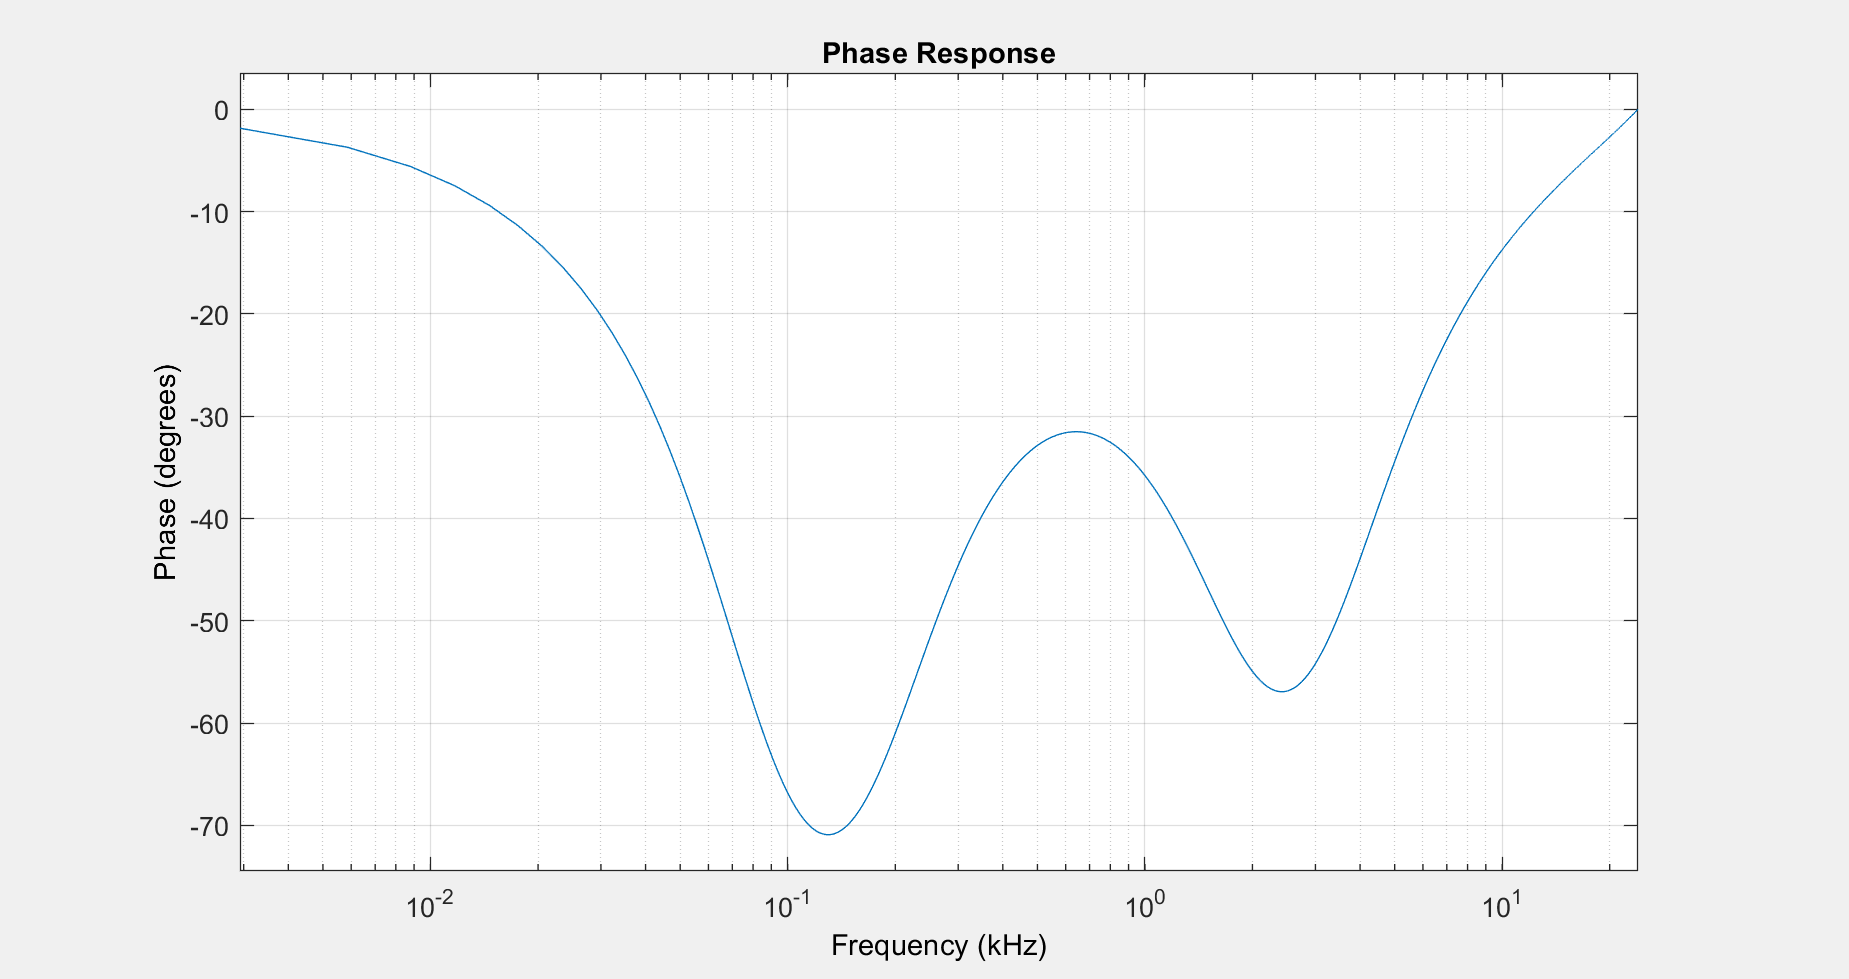

fvtool(Hcas, 'Analysis', 'phase', 'Fs', Fs);

fdsklvksd

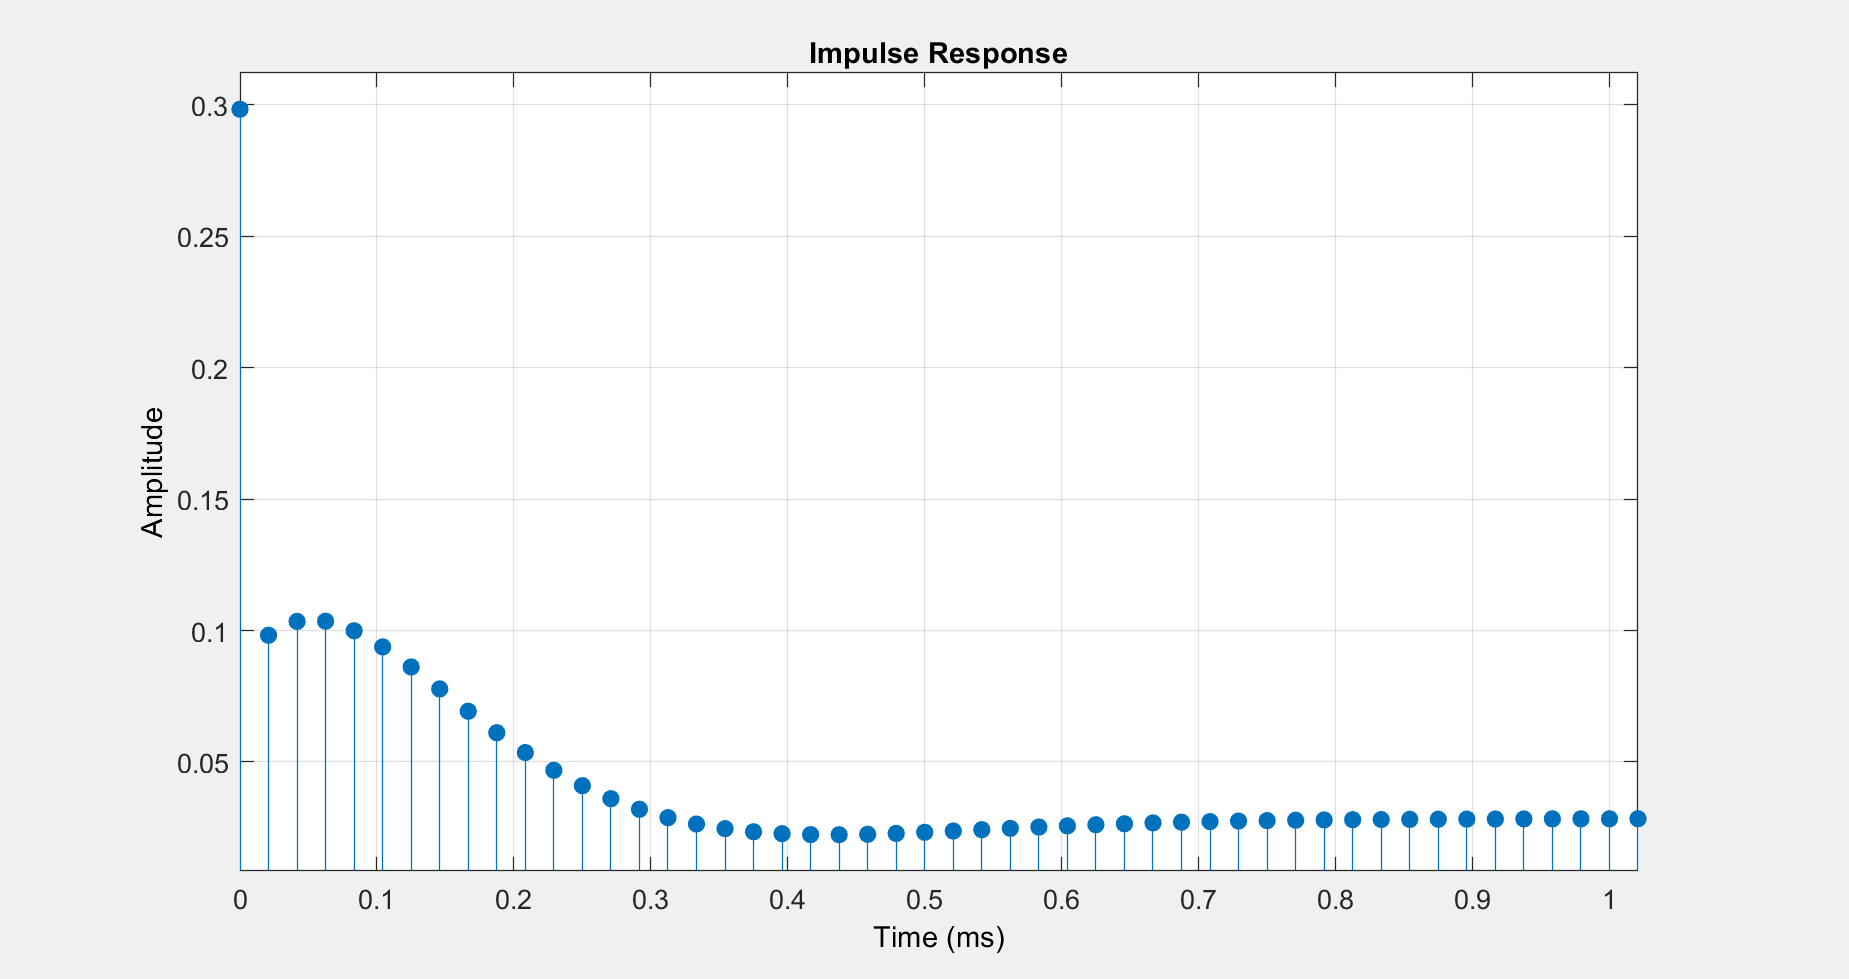

fvtool(Hcas, 'Analysis', 'impulse', 'Fs', Fs);

## Konklusion